# Q1Q2 Investigation

Live script to show combination of Q1 and Q2 on a strip length. Right now we use a strip length of 1.4 m.

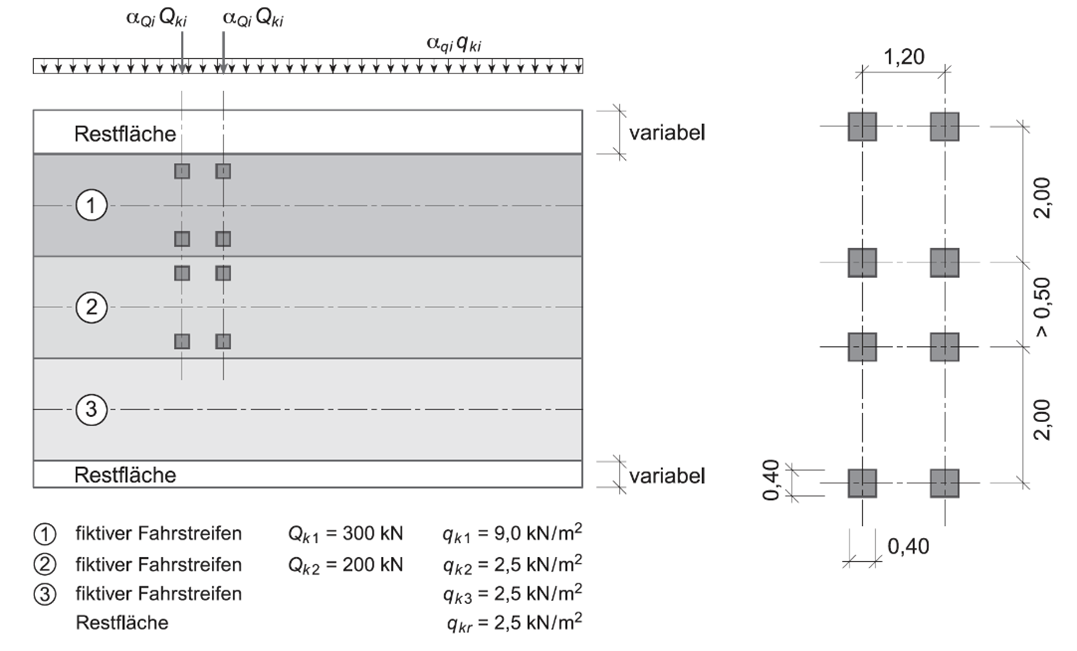

We will come at the problem from 2 angles:

- First, we solve the problem using the typical equations in Annex C of SIA 269

- Second, we perform tail fitting and try to use return period to get the design value

- Finally, we compare the two methods

% Initial commands
clear, clc, close all
% This function loads the variable 'MaxEvents' which is produced by 'MATSimAxles'
load('Q1Q2MaxEventsx.mat');
% Convert ClassT to m (number) form m = 1 is All, m = 2 is ClassOW, m = 3 is Class
MaxEvents.m(strcmp(MaxEvents.ClassT,"All")) = 1;
MaxEvents.m(strcmp(MaxEvents.ClassT,"ClassOW")) = 2;
MaxEvents.m(strcmp(MaxEvents.ClassT,"Class")) = 3; MaxEvents.ClassT = [];
% Alter Speed
MaxEvents.L1Sp = MaxEvents.L1Sp/100;
MaxEvents.L2Sp = MaxEvents.L2Sp/100;

### Step 1: Input desired filters/parameters

% Select which year to analyze
Years = 0;
%Years = 2011:2019;

% Select stations (locations) to analyze
Stations = 0;
%Stations = [408 409 405 406 402 415 416];

% Block Maxima (always use j)
BM = {'Daily', 'Weekly', 'Yearly'};

% Select which Classification you want to analyze (always use i)
% Must be in the order 'All' 'ClassOW' 'Class' due to deletions
ClassType = {'All', 'ClassOW', 'Class'};


### Step 2: Filter Axles based on desired year and station (location)

% Filter Axles based on desired year and station (location)
if Stations > 0
    y = MaxEvents.ZST == Stations;
    MaxEvents(~any(y,2),:) = [];
end
if Years > 0
    y = year(MaxEvents.Time) == Years;
    MaxEvents(~any(y,2),:) = [];
end


### Step 3: Build Structure with Block Maxima

% Transform AxTandem into Array (necessary for splitapply)
Z = MaxEvents;
Z.Time = datenum(Z.Time);
Z = table2array(Z);
            
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    % Filter based on Class - MaxEvents is compromised after this (deleting entries)
    if strcmp(Class,'ClassOW')
        MaxEvents(MaxEvents.m == 1,:) = []; %#ok<*SAGROW> 
        Z(Z(:,end) == 1,:) = [];
    elseif strcmp(Class,'Class')
        MaxEvents(MaxEvents.m == 1,:) = [];
        Z(Z(:,end) == 1,:) = [];
        MaxEvents(MaxEvents.m == 2,:) = [];
        Z(Z(:,end) == 2,:) = [];
    end
      
    for j = 1:length(BM)
        BlockM = BM{j};
        
        % Initialize
        Max.(Class).(BlockM) = [];
        
        if strcmp(BlockM,'Daily')
            
            % Make groups out of unique locations and days
            [Gr, GrIDDay, GrIDZST] = findgroups(dateshift(MaxEvents.Time,'start','day'),MaxEvents.ZST);
            
        elseif strcmp(BlockM,'Weekly')
            
            [Gr, GrIDWeek, GrIDZST] = findgroups(dateshift(MaxEvents.Time,'start','week'),MaxEvents.ZST);
            
        else
            
            [Gr, GrIDYear, GrIDZST] = findgroups(year(MaxEvents.Time),MaxEvents.ZST);
            
        end
        
        % Perform splitapply (see function at end... not just Max as we want whole rows involving maxes)
        Max.(Class).(BlockM) = splitapply(@(Z)maxIndex(Z),Z,Gr);
        % Transform back into table form
        Max.(Class).(BlockM) = array2table(Max.(Class).(BlockM));
        Max.(Class).(BlockM).Properties.VariableNames = {'R', 'ZST', 'Max', 'DayRank', 'L1Veh', 'L2Veh', 'L1Load', 'L2Load', 'L1Ax', 'L2Ax', 'L1Sp', 'L2Sp', 'Time', 'm'};
        Max.(Class).(BlockM).Time = datetime(Max.(Class).(BlockM).Time,'ConvertFrom',"datenum"); Max.(Class).(BlockM).R = [];
        
    end  
end

#### Curve Fitting

% Set Distribution Types
DistTypes = {'Normal', 'Lognormal', 'GeneralizedExtremeValue'};

% Set CDF Scaling Factors for estimates
D2WFactor = 5; W2YFactor = 50; D2YFactor = D2WFactor*W2YFactor;

% Set x values to be use globally
x_values = 0:1:1000;

% Fit Block Maxima to Normal Curve
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    for j = 1:length(BM)
        BlockM = BM{j};
        
        for k = 1:length(DistTypes)
            Dist = DistTypes{k};
   
            pd.(Class).(BlockM).(Dist) = fitdist(Max.(Class).(BlockM).Max,Dist);
            y_values.(Class).(BlockM).(Dist).PDF_Fit = pdf(pd.(Class).(BlockM).(Dist),x_values);
            y_values.(Class).(BlockM).(Dist).CDF_Fit = cdf(pd.(Class).(BlockM).(Dist),x_values);
            
            if strcmp(BlockM,'Daily')
                y_values.(Class).('Weekly').(Dist).CDF_D2W = y_values.(Class).(BlockM).(Dist).CDF_Fit.^D2WFactor;
                y_values.(Class).('Weekly').(Dist).PDF_D2W = [0 diff(y_values.(Class).('Weekly').(Dist).CDF_D2W)];
                y_values.(Class).('Yearly').(Dist).CDF_D2Y = y_values.(Class).(BlockM).(Dist).CDF_Fit.^D2YFactor;
                y_values.(Class).('Yearly').(Dist).PDF_D2Y = [0 diff(y_values.(Class).('Yearly').(Dist).CDF_D2Y)];
                
                if strcmp(Dist,'Normal')
                    mu = trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,(x_values-mu).^2));
                    pd.(Class).D2W.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                    
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,(x_values-mu).^2));
                    pd.(Class).D2Y.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                elseif strcmp(Dist,'Lognormal')
                    mu = trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,(x_values-mu).^2));
                    zeta = sqrt(log(1+(sigma/mu)^2));
                    lambda = log(mu)-0.5*zeta^2;
                    pd.(Class).D2W.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                    
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,(x_values-mu).^2));
                    zeta = sqrt(log(1+(sigma/mu)^2));
                    lambda = log(mu)-0.5*zeta^2;
                    pd.(Class).D2Y.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                end

            elseif strcmp(BlockM,'Weekly')
                y_values.(Class).('Yearly').(Dist).CDF_W2Y = y_values.(Class).(BlockM).(Dist).CDF_Fit.^W2YFactor;
                y_values.(Class).('Yearly').(Dist).PDF_W2Y = [0 diff(y_values.(Class).('Yearly').(Dist).CDF_W2Y)];
                
                if strcmp(Dist,'Normal')
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,(x_values-mu).^2));
                    pd.(Class).W2Y.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                    
                elseif strcmp(Dist,'Lognormal')
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,(x_values-mu).^2));
                    zeta = sqrt(log(1+(sigma/mu)^2));
                    lambda = log(mu)-0.5*zeta^2;
                    pd.(Class).W2Y.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                    
                end
                
            end
        end
    end
end


### Step 4: Plot Block Maxima

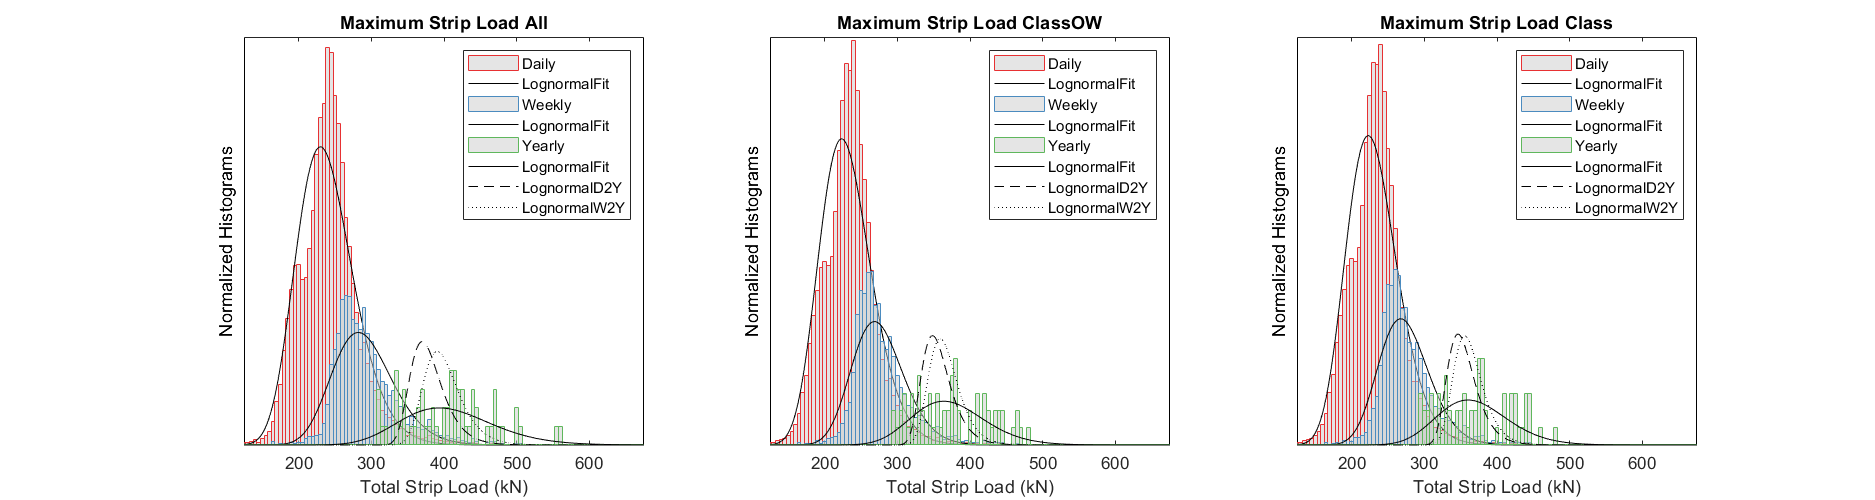

figure('Position',[0 0 1500 400]);

% Set colours
C = linspecer(9);
% ScaleDown
ScaleDown = [1 2.5 5];
% X Stuff
Step = 5;
LimitL = 100;
LimitR = 700;
X = LimitL:Step:LimitR;
x = X(1:end-1) + diff(X);
    
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    subplot(1,3,i)
    hold on
    
    for j = 1:length(BM)
        BlockM = BM{j};
        
        y = histcounts(Max.(Class).(BlockM).Max,'BinEdges',X,'normalization','pdf');
        bar(x,y/ScaleDown(j),1,'EdgeColor',C(j,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.5,'DisplayName',BlockM)
        
        for k = 2
            Dist = DistTypes{k};
       
            plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_Fit/ScaleDown(j),'k-','DisplayName',[Dist 'Fit'])
            
            if strcmp(BlockM,'Yearly')
                
                plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_D2Y/ScaleDown(j),'k--','DisplayName',[Dist 'D2Y'])
                plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_W2Y/ScaleDown(j),'k:','DisplayName',[Dist 'W2Y'])
            end
            
        end
    end
    
    % Set Plot Details
    set(gca,'ytick',[],'yticklabel',[],'ycolor','k')
    box on
    xlim([LimitL+25 LimitR-25])
    ylabel('Normalized Histograms')
    xlabel('Total Strip Load (kN)')
    title(['Maximum Strip Load ' Class])
    legend('location','northeast')
    
end

#### *Block Maxima Compared between each other*

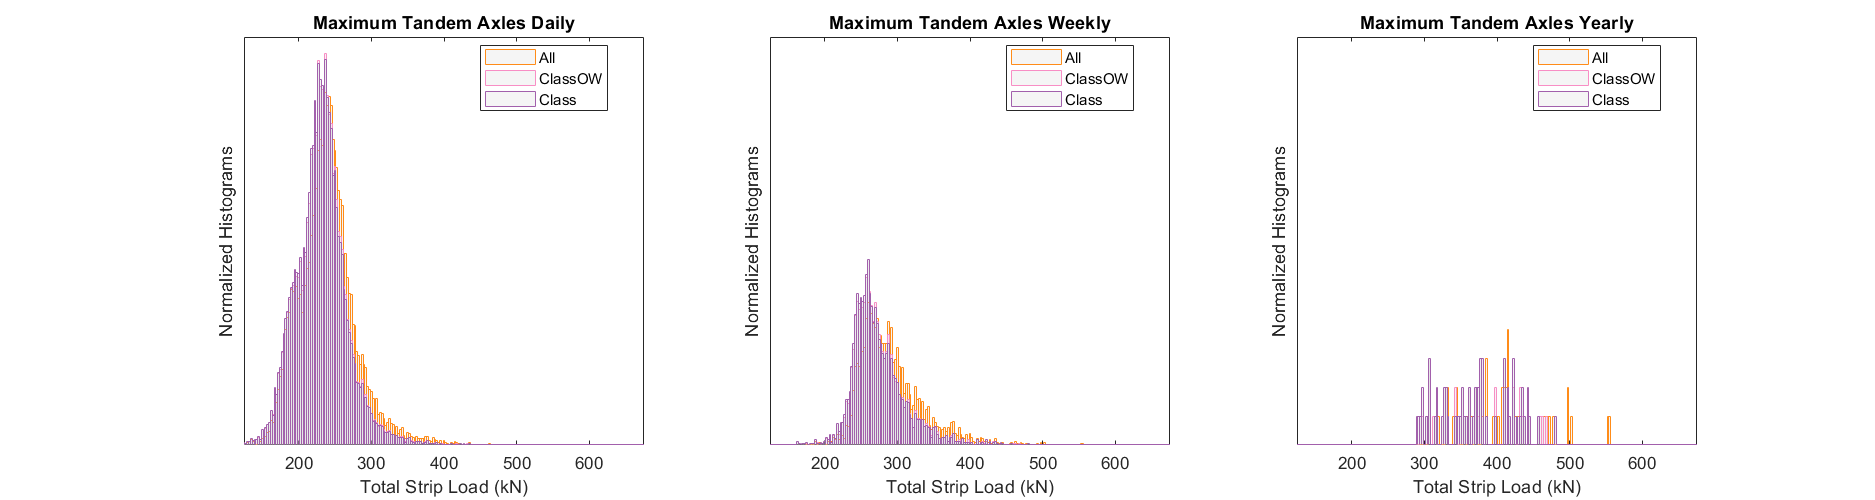

figure('Position',[0 0 1500 400]);

% X Stuff
Step = 2.5;
LimitL = 100;
LimitR = 700;
Xp = LimitL-Step/2:Step:LimitR-Step/2;

for j = 1:length(BM)
    BlockM = BM{j};
    
    subplot(1,3,j)
    hold on
    
    histogram(Max.All.(BlockM).Max,'BinEdges',Xp,'normalization','pdf','EdgeColor',C(4,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.2,'DisplayName','All')
    histogram(Max.ClassOW.(BlockM).Max,'BinEdges',Xp,'normalization','pdf','EdgeColor',C(7,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.2,'DisplayName','ClassOW')
    histogram(Max.Class.(BlockM).Max,'BinEdges',Xp,'normalization','pdf','EdgeColor',C(9,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.2,'DisplayName','Class')
    
    % Set Plot Details
    a = ylim;
    ylim([a(1) a(2)*j])
    box on
    set(gca,'ytick',[],'yticklabel',[])
    ylabel('Normalized Histograms')
    xlabel('Total Strip Load (kN)')
    title(['Maximum Tandem Axles ' BlockM])
    legend('location','best')
    xlim([LimitL+25 LimitR-25])
    
end

#### *Block Maxima Compared for Classification Filters*

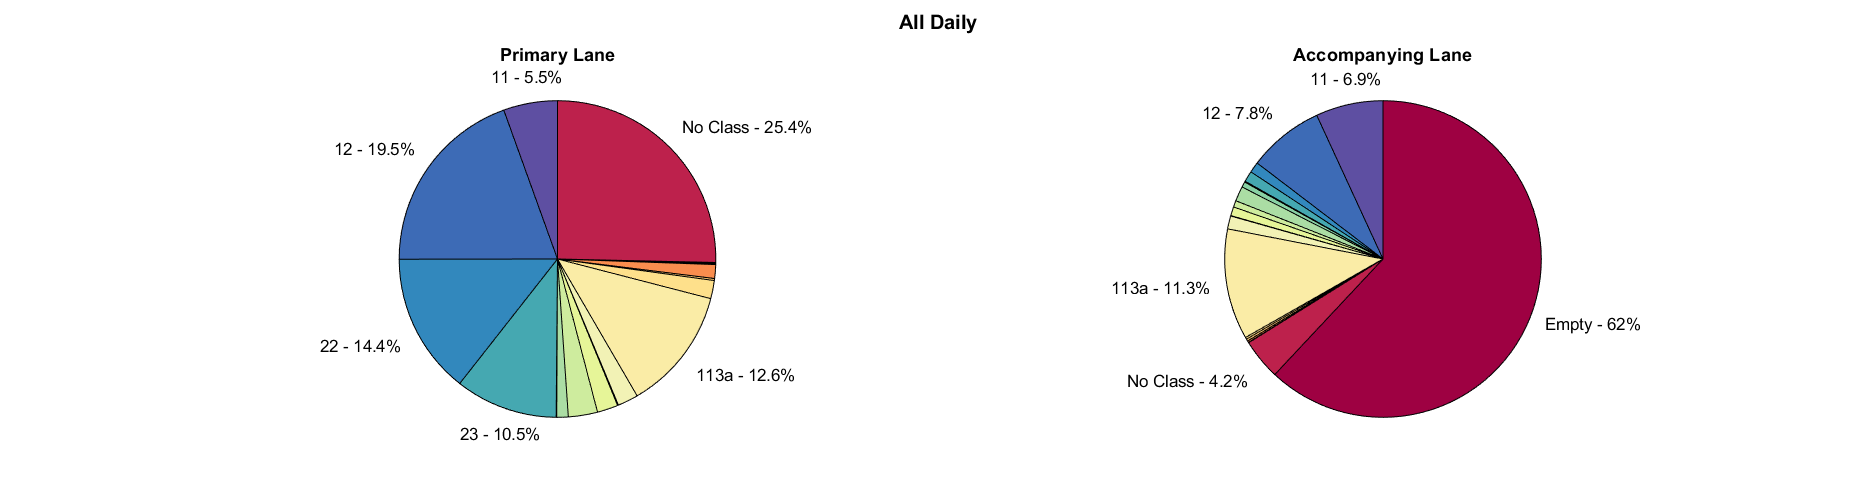

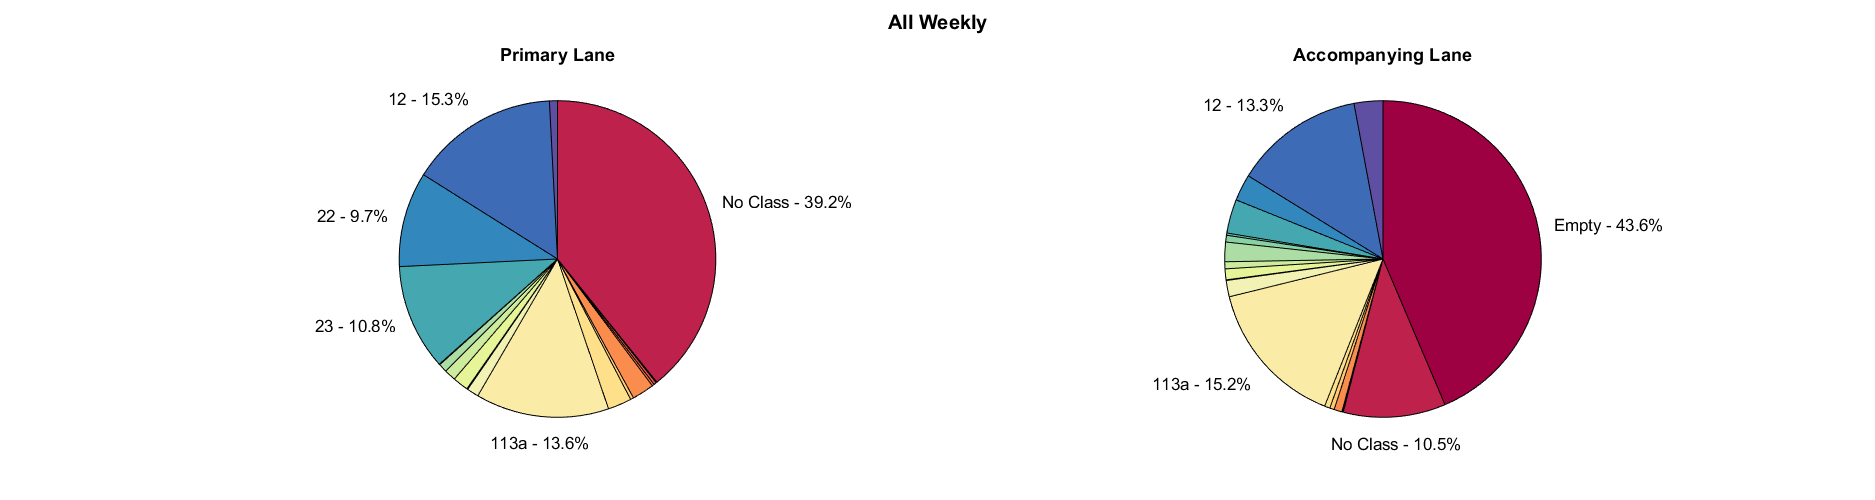

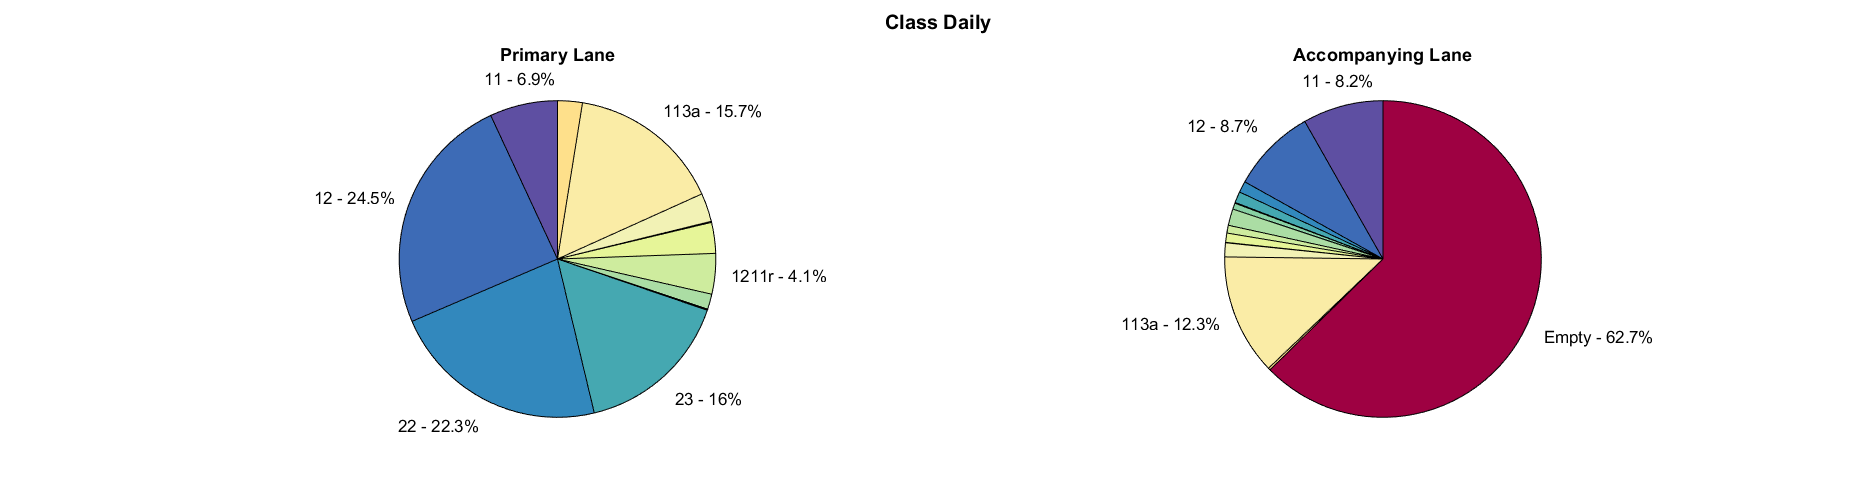

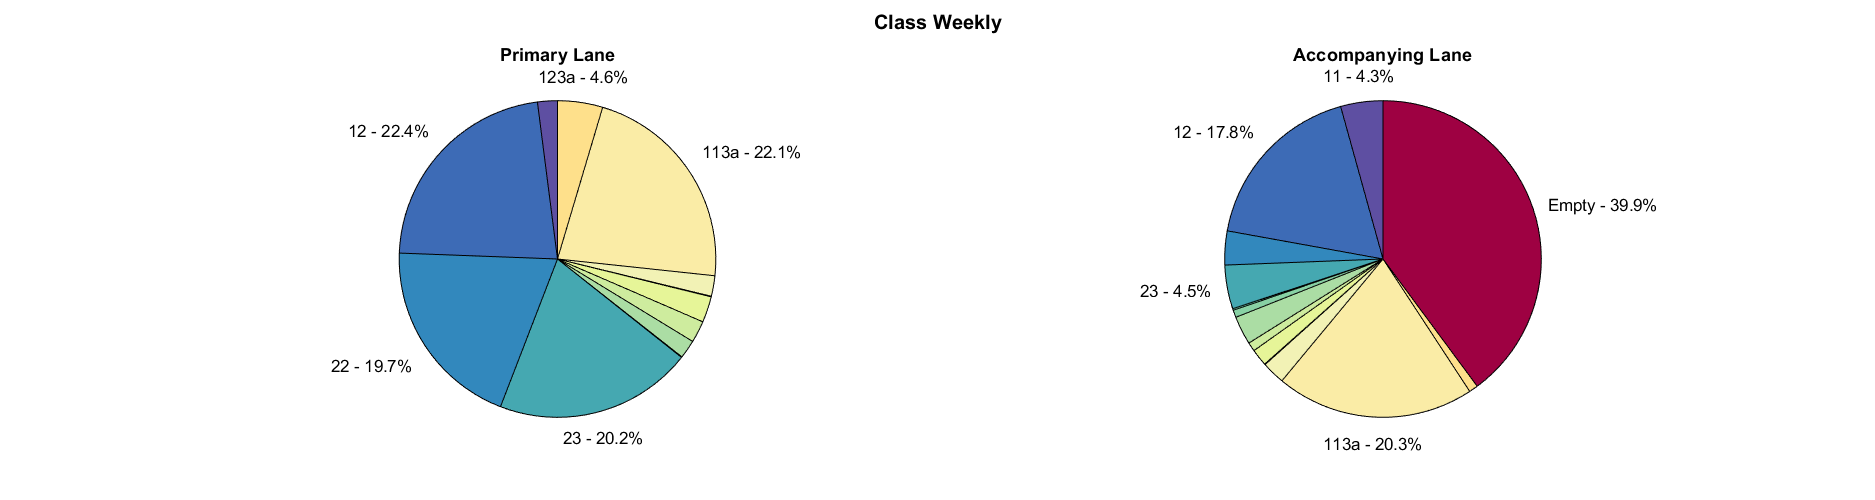

%sum(Max.All.Daily.L1Load)./sum(Max.All.Daily.L2Load)
%histogram(hour(Max.All.Daily.Time),'normalization','pdf')

% All TrTyps in number format
TrTyps = [11; 12; 22; 23; 111; 11117; 1127; 12117; 122; 11127; 1128; 1138; 1238; 41; 42; 43; 44; 45; 46; 0; 99];

% TrTyps in Label format
TrName{1} = '11'; TrName{2} = '12'; TrName{3} = '22'; TrName{4} = '23'; TrName{5} = '111'; TrName{6} = '1111r'; TrName{7} = '112r'; 
TrName{8} = '1211r'; TrName{9} = '122'; TrName{10} = '1112r'; TrName{11} = '112a'; TrName{12} = '113a'; TrName{13} = '123a'; 
TrName{14} = '5ax 60t'; TrName{15} = '6ax 60t'; TrName{16} = '7ax 72t'; TrName{17} = '8ax 84t'; TrName{18} = '9ax 96t'; 
TrName{19} = '8ax 96t';  TrName{20} = 'No Class'; TrName{21} = 'Empty'; TrName = TrName';

% Convert from Cell to String
TN = strings(size(TrName)); [TN{:}] = TrName{:};

% For each ClassType (or in this case just All and Class)
for i = 1:2:3
    Class = ClassType{i};
    
    % Select Daily, Weekly, or Yearly
    for j = 1:2%:3
        BlockM = BM{j};
        
        figure('Position',[0 0 1500 400]);
        hold on
        
        % Get Primary Lane and Accompanying Lane Vehicles
        Primary = zeros(height(Max.(Class).(BlockM)),1); Accomp = Primary;
        [~, Ind] = max([Max.(Class).(BlockM).L1Load'; Max.(Class).(BlockM).L2Load']); Ind = Ind';
        Primary(Ind == 1) = Max.(Class).(BlockM).L1Veh(Ind == 1); Primary(Ind == 2) = Max.(Class).(BlockM).L2Veh(Ind == 2);
        Accomp(Ind == 1) = Max.(Class).(BlockM).L2Veh(Ind == 1); Accomp(Ind == 2) = Max.(Class).(BlockM).L1Veh(Ind == 2);
        
        PrimaryC = categorical(Primary); AccompC = categorical(Accomp);
        [N, Cats] = histcounts(PrimaryC,categorical(TrTyps)); [Nx] = histcounts(AccompC,categorical(TrTyps));
        
        Label = cell(length(TN),1); Labelx = cell(length(TN),1);
        Perc = 100*N/sum(N); Percx = 100*Nx/sum(Nx);
        PercS = string(round(Perc,1))'; PercSx = string(round(Percx,1))';
        
        for p = 1:length(TN)
            if Perc(p) > 4
                Label{p} = [TN{p} ' - ' PercS{p} '%'];  else;  Label{p} = '';
            end
            if Percx(p) > 4
                Labelx{p} = [TN{p} ' - ' PercSx{p} '%'];  else;  Labelx{p} = '';
            end
        end
        
        % We need colors to be the same for each TrTyp
        % Labels should be strings that include the percentages
        
        subplot(1,2,1)
        sgtitle([Class ' ' BlockM],'fontweight','bold','fontsize',12);
        h = pie(N,Label);
        newColors = linspecer(numel(N));
        % Isolate the patch handles
        patchHand = findobj(h, 'Type', 'Patch');
        % Set the color of all patches using the nx3 newColors matrix
        set(patchHand, {'FaceColor'}, mat2cell(newColors, ones(size(newColors,1),1), 3))
        title('Primary Lane')
        subplot(1,2,2)
        h = pie(Nx,Labelx);
        % Isolate the patch handles
        patchHand = findobj(h, 'Type', 'Patch');
        set(patchHand, {'FaceColor'}, mat2cell(newColors, ones(size(newColors,1),1), 3))
        title('Accompanying Lane')
        
        if strcmp(Class,'All') && strcmp(BlockM,'Daily')
            NAD = N + Nx; NAD = NAD/sum(NAD);
        elseif  strcmp(Class,'All') && strcmp(BlockM,'Weekly')
            NAY = N + Nx; NAY = NAY/sum(NAY);
        end
        
    end
end

#### *Classification of Vehicles Involved*

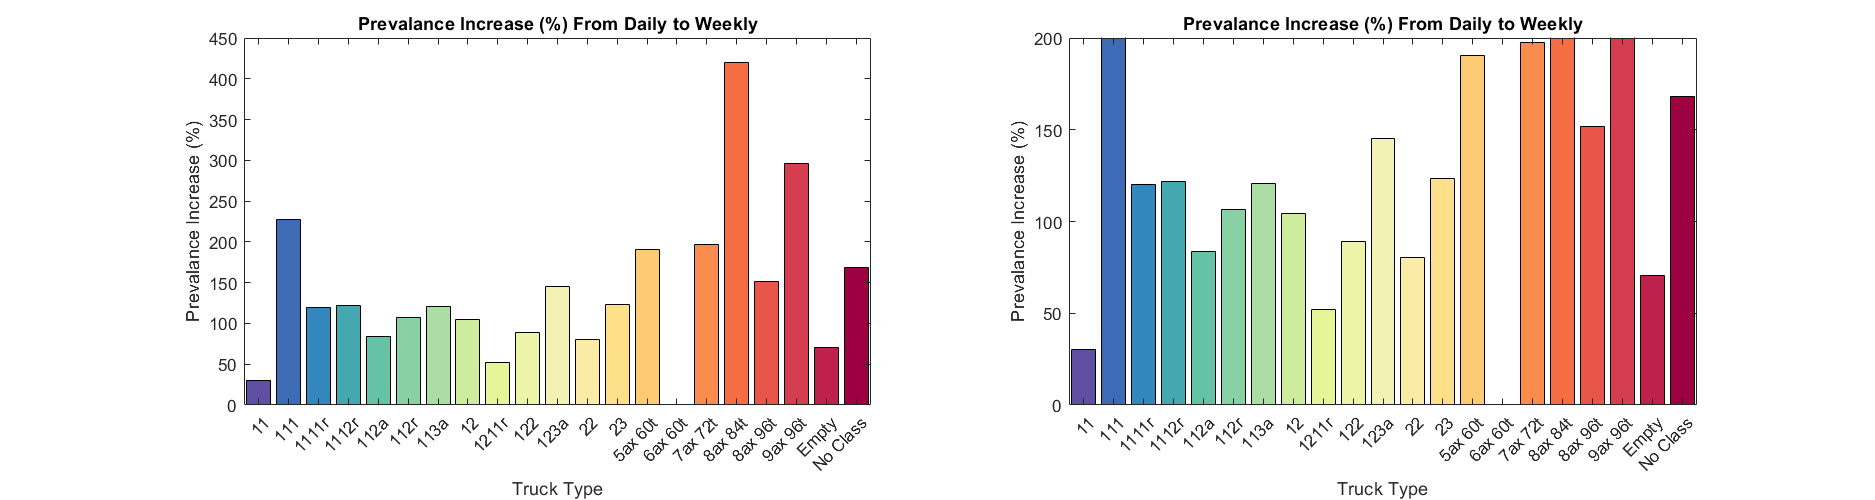

% One question is: how much more prevalent is the TrTyp in the maximums
% than in the normal traffic? Who are the heavy ppl? Use ClassOW
% Need to fetch avg prevalance of TrTyps from somewhere...

% Lets do the comparison between AllDaily and AllYearly

figure('Position',[0 0 1500 400]);
subplot(1,2,1)
b = bar(categorical(TN),100*NAY./NAD);
b.FaceColor = 'flat';
b.CData(:,:) = newColors;
ylabel('Prevalance Increase (%)')
xlabel('Truck Type')
title('Prevalance Increase (%) From Daily to Weekly')


subplot(1,2,2)
b = bar(categorical(TN),100*NAY./NAD);
b.FaceColor = 'flat';
b.CData(:,:) = newColors;
ylabel('Prevalance Increase (%)')
ylim([0 200])
xlabel('Truck Type')
title('Prevalance Increase (%) From Daily to Weekly')

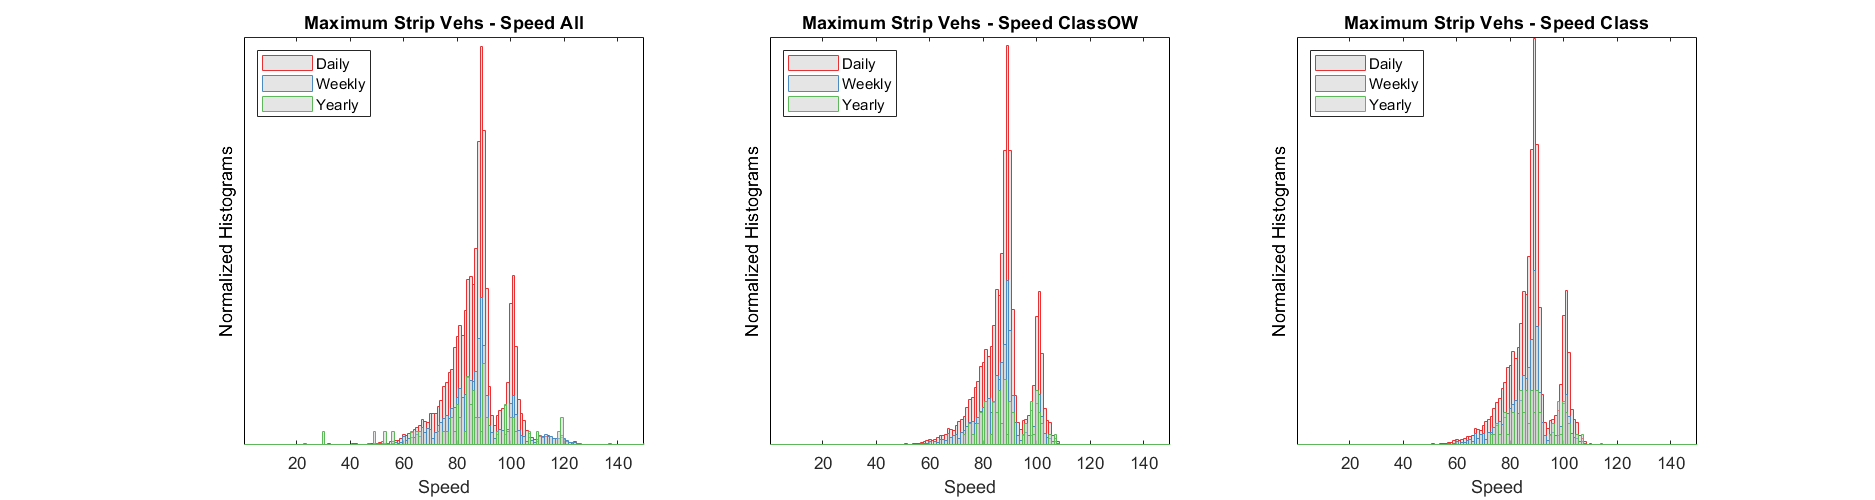

% I should add SPEED
figure('Position',[0 0 1500 400]);

% X Stuff
Step = 1;
LimitL = 0;
LimitR = 150;
X = LimitL:Step:LimitR;
%Xp = LimitL-Step/2:Step:LimitR-Step/2;
x = X(1:end-1) + diff(X);

for i = 1:length(ClassType)
    Class = ClassType{i};
    
    subplot(1,3,i)
    hold on
    
    for j = 1:length(BM)
        BlockM = BM{j};
        
        y = histcounts(Max.(Class).(BlockM).L1Sp(Max.(Class).(BlockM).L1Sp>0),'BinEdges',X,'normalization','pdf');
        bar(x,y/ScaleDown(j),1,'EdgeColor',C(j,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.5,'DisplayName',BlockM)
        
    end
    
    % Set Plot Details
    set(gca,'ytick',[],'yticklabel',[],'ycolor','k')
    box on
    xlim([LimitL+.25 LimitR-.25])
    ylabel('Normalized Histograms')
    xlabel('Speed')
    title(['Maximum Strip Vehs - Speed ' Class])
    legend('location','northwest')
    
end

### Step 5: Summarize $\alpha_Q$ Estimates


% According to Annex C of SIA 269
Beta.Yearly = 4.7; % Here we use the Beta annual - so we should use annual max effects
Beta.Weekly = 5.44422; % See Tail Fitting > Beta Conversion
Beta.Daily = 5.72397;
Alpha = 0.7;

% Right now we assume a normal distribution in the Edact calculation. Also
% perform for lognormal.

% Initialize SumTable
SumTableNorm = array2table(zeros(6,length(BM)*length(ClassType)));
SumTableLogNormComp = array2table(zeros(5,length(BM)*length(ClassType)));
SumTableNorm.Properties.VariableNames = {[BM{3} ' ' ClassType{3}], [BM{3} ' ' ClassType{2}], [BM{3} ' ' ClassType{1}], [BM{2} ' ' ClassType{3}],...
    [BM{2} ' ' ClassType{2}], [BM{2} ' ' ClassType{1}], [BM{1} ' ' ClassType{3}], [BM{1} ' ' ClassType{2}], [BM{1} ' ' ClassType{1}]};
SumTableLogNorm = SumTableNorm;
SumTableNorm.Properties.RowNames = {'Mu', 'Sigma', 'COV (%)', '95th %', 'Dist 95', 'AlphaQ'};
SumTableLogNorm.Properties.RowNames = {'Lambda', 'Zeta', '95th %', 'Dist 95', 'AlphaQN', 'AlphaQLN'};
SumTableLogNormComp.Properties.RowNames = {'Lambda', 'Zeta', '95th %', 'Dist 95', 'AlphaQLN Est'};
SumTableLogNormComp.Properties.VariableNames = {[BM{3} ' ' ClassType{3}], [BM{3} ' ' ClassType{2}], [BM{3} ' ' ClassType{1}], ['W2Y ' ClassType{3}],...
    ['W2Y ' ClassType{2}], ['W2Y ' ClassType{1}], ['D2Y ' ClassType{3}], ['D2Y ' ClassType{2}], ['D2Y ' ClassType{1}]};

for i = 1:length(ClassType)
    Class = ClassType{i};

    for j = 1:length(BM)
        BlockM = BM{j};
            
        Emact = mean(Max.(Class).(BlockM).Max);
        Stdev = std(Max.(Class).(BlockM).Max);
        COV = Stdev/Emact;
        Delta2 = log(COV^2+1);
        N5 = prctile(Max.(Class).(BlockM).Max,95);     
        Dist95N = norminv(0.95,pd.(Class).(BlockM).Normal.mu,pd.(Class).(BlockM).Normal.sigma);
        Dist95LN = logninv(0.95,pd.(Class).(BlockM).Lognormal.mu,pd.(Class).(BlockM).Lognormal.sigma);

*We account for the fact that the reliability index, *$\beta$, *must be for the same reference period as *$E_{m,\textrm{act}}$

Normal Distribution:                            $E_{d,\textrm{act}} =E_{m,\textrm{act}} \cdot \left\lbrack 1+\alpha \beta \nu \right\rbrack$

Lognormal Distribution:                      $E_{d,\textrm{act}} =E_{m,\textrm{act}} \cdot \exp \left\lbrack \alpha \beta \delta -0\ldotp 5\delta^2 \right\rbrack$      where         $\delta^2 =\ln \left(\nu^2 +1\right)$

        
        EdactN = Emact*(1+Alpha*Beta.(BlockM)*COV);
        AlphaQN = EdactN/(1000*1.5);

               Yearly Class    Yearly ClassOW    Yearly All    Weekly Class    Weekly ClassOW    Weekly All    Daily Class    Daily ClassOW    Daily All
               ____________    ______________    __________    ____________    ______________    __________    ___________    _____________    _________

    Mu            369.70           373.83          408.50         274.18           275.59          291.27        231.17          231.81         239.87  
    Sigma          48.93            50.51           68.04          36.69            37.72           44.97         35.54           36.02          40.79  
    COV (%)        13.23      

        EdactLN = Emact*exp(Alpha*Beta.(BlockM)*sqrt(Delta2)-0.5*Delta2);

                Yearly Class    Yearly ClassOW    Yearly All    Weekly Class    Weekly ClassOW    Weekly All    Daily Class    Daily ClassOW    Daily All
                ____________    ______________    __________    ____________    ______________    __________    ___________    _____________    _________

    Lambda           5.90             5.91            6.00           5.61             5.61            5.66          5.43            5.43           5.47  
    Zeta             0.13             0.14            0.16           0.13             0.13            0.14          0.16            0.16           0.17  
    95th %         444.04 

        AlphaQLN = EdactLN/(1000*1.5);

                    Yearly Class    Yearly ClassOW    Yearly All    W2Y Class    W2Y ClassOW    W2Y All    D2Y Class    D2Y ClassOW    D2Y All
                    ____________    ______________    __________    _________    ___________    _______    _________    ___________    _______

    Lambda               5.90             5.91            6.00         5.89          5.90         5.99        5.87          5.88         5.94 
    Zeta                 0.13             0.14            0.16         0.06          0.06         0.07        0.06          0.06         0.07 
    95th %             444.04           460.94          520.67       4


        SumTableNorm.([BlockM ' ' Class]) = [Emact; Stdev; 100*COV; N5; Dist95N; AlphaQN];
        SumTableLogNorm.([BlockM ' ' Class]) = [pd.(Class).(BlockM).Lognormal.mu; pd.(Class).(BlockM).Lognormal.sigma; N5; Dist95LN; AlphaQN; AlphaQLN];
        
        if strcmp(BlockM,'Weekly')
            pdx = pd.(Class).W2Y.Lognormal;
            Delta2 = pdx.sigma^2;
            Emact = exp(pdx.mu+0.5*Delta2);
            SumTableLogNormComp.(['W2Y ' Class]) = [pdx.mu; pdx.sigma; prctile(Max.(Class).Yearly.Max,95); logninv(0.95,pdx.mu,pdx.sigma); Emact*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2)/(1000*1.5)];
        elseif strcmp(BlockM,'Daily')
            pdx = pd.(Class).D2Y.Lognormal;
            Delta2 = pdx.sigma^2;
            Emact = exp(pdx.mu+0.5*Delta2);
            SumTableLogNormComp.(['D2Y ' Class]) = [pdx.mu; pdx.sigma; prctile(Max.(Class).Yearly.Max,95); logninv(0.95,pdx.mu,pdx.sigma); Emact*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2)/(1000*1.5)];
        else
            SumTableLogNormComp.([BlockM ' ' Class]) = [pd.(Class).(BlockM).Lognormal.mu; pd.(Class).(BlockM).Lognormal.sigma; N5; Dist95LN; AlphaQLN];
        end

    end
end

format bank 
disp(SumTableNorm)
disp(SumTableLogNorm)
disp(SumTableLogNormComp)

### Step 6: Probability Paper Plotting & Tail Fitting Methods

When we apply the above equations, we are assuming the maximums are normally or log-normally distributed. We should evaluate the fit with a probability paper plot.

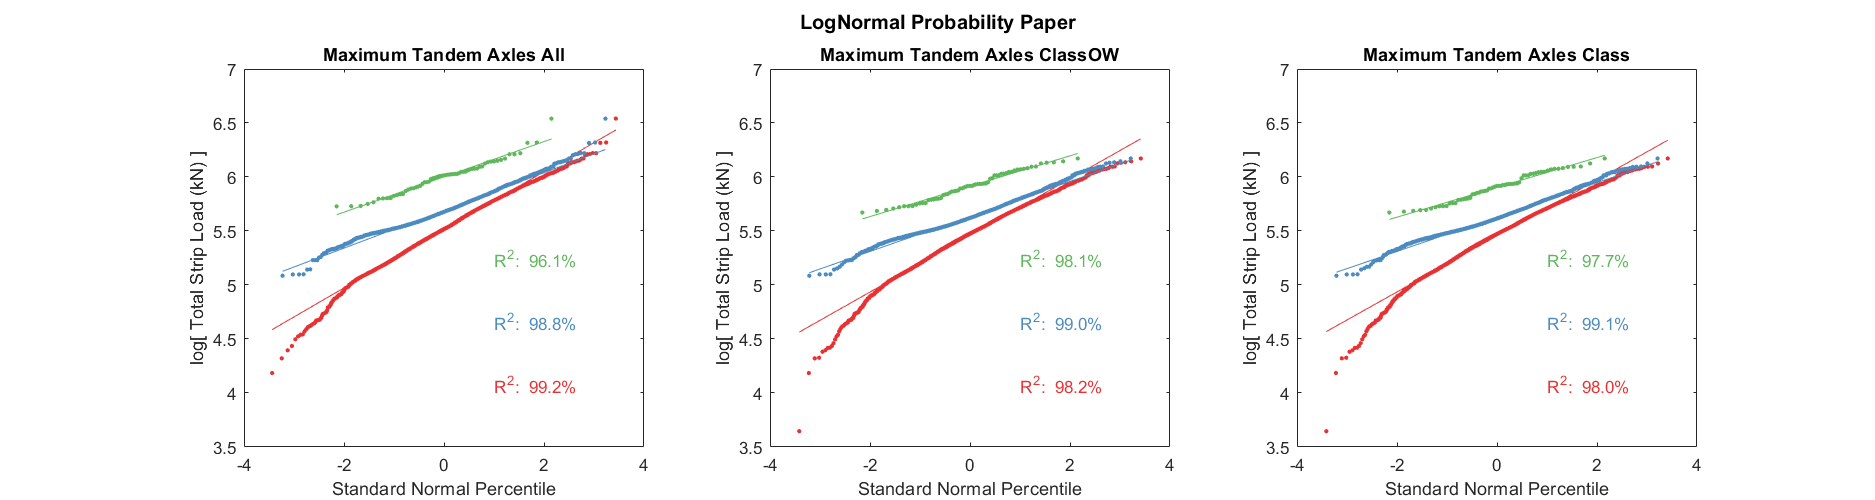

figure('Position',[0 0 1500 400]);

   
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    for j = 1:length(BM)
        BlockM = BM{j};
        subplot(1,3,i)
        hold on
        
        [MaxECDF, MaxECDFRank] = ecdf(Max.(Class).(BlockM).Max); MaxECDFRank = MaxECDFRank'; MaxECDF(1) = []; MaxECDFRank(1) = [];
        
        scatter(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),log(MaxECDFRank),7,C(j,:),'filled','DisplayName','Max Data');
        mdl = fitlm(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),log(MaxECDFRank),'linear');
        
        x2 = norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1));
        y2 = log(MaxECDFRank);
        
        md2 = fitlm(x2(round(length(x2)*3/4):length(x2)),y2(round(length(x2)*3/4):length(x2)),'linear');
        
        plot(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),mdl.Fitted,'-','Color',C(j,:),'DisplayName',['Fitted ' num2str(mdl.Rsquared.Ordinary,3)]);
        %plot(x2(round(length(x2)*3/4):length(x2)),md2.Fitted,'-','Color','k','DisplayName',['Fitted ' num2str(md2.Rsquared.Ordinary,3)]);
        
        
        %text(1,y1(1)+(y1(2)-y1(1))/j,['\lambda = ' sprintf('%.2f \n',mdl.Coefficients.Estimate(1)) '\zeta = ' sprintf('%.2f \n',mdl.Coefficients.Estimate(2)) sprintf('R^2:  %.1f%%',mdl.Rsquared.Ordinary*100)])

        box on
        xlim([-4 4])
        ylim([3.5 7])
        y1 = ylim;
        text(1,y1(1)+(y1(2)-y1(1))*(j/6),sprintf('R^2:  %.1f%%',mdl.Rsquared.Ordinary*100),"Color",C(j,:))
        
        ylabel('log[ Total Strip Load (kN) ]')
        xlabel('Standard Normal Percentile')
        %legend('Location', 'southeast')
        
    end
    
    title(['Maximum Tandem Axles ' Class])
    
end

sgtitle('LogNormal Probability Paper','fontweight','bold','fontsize',12);

#### Function(s)

function out = maxIndex(Z)
    [ymax, loc]=max(sum([Z(:,6) Z(:,7)],2));
    out=[ymax, Z(loc,:)];
end